# Finalizing the Solution

The goal of this script, Final_solution.mlx, is to take the solution data of the inefficient path that goes through all 10 cities that we get from Path.mlx, and output our final solution data along with displays of the relevent data surrounding the final solution.

We achieve our final solution by using homotopy to increase the value of r from r = 0.5, as in the solution found in Path.mlx, to r = 10,000, allowing for a much smaller time (~19.92 seconds to 13.321614 seconds). This is done by feeding the current best solution into the guess of the next solution solver function, `bvp4c`, each time increasing the value of r by some amount. By iterating in this way, we can achieve a much more efficient solution.

We stopped at r = 10,000 because at this point, the decrease in time with each scaled iteration is much too small for it to be worthwhile to continue iterating.

### Loading Path.mlx solution

The purpose of this code section is to load the solution data from Path.mlx.

clear
close all
clc

load ColonParenthesis_path.mat
newsol = solution.sol;
city_sequence = solution.city_sequence;

## Homotopy to Increase r

This section is where the homotopy is implemented to achieve a much more efficient path where the time improves from ~19.92 seconds to 13.321614 seconds.

We needed to increase r because we added the term $\frac{1}{r}\left(\gamma^2+a^2\right)$ to our cost function. By increasing r, this factor goes to zero, allowing our cost to be minimized. We needed to add this term in the cost function to allow the Hamiltonian to not be linear in terms of γ and a. Without this term, the values of γ and a would be discontinuous with time, which our solver, `bvp4c`, cannot handle.

### First Iterations from r = 0.5 up to r = 1.9

This is the first set of iterations of our homotopy solution.

We found that after r = 1.975, `bvp4c` couldn't find a solution with a small enough mesh size it could handle. We stopped our first iteration at this point to try to find a way we could continue iterating. We then saved our data at the last working solution `bvp4c` could give without an error.

% Initializes the variables in the loop
r = 0.5:(1.975-0.5)/5:1.975; % "Broke" at r = 1.975
final_time = zeros(length(r),1);

% Homotopy loop to iterate the solution by increasing r
for i = 1:length(r)

    r_iteration = r(i);
    newsol = bvp4c(@(t,s,times)ODEmain(t,s,times,r_iteration), @(so,sf,times)bcfunc(so,sf,times,r_iteration,city_sequence), newsol);

    % Calculates the final time for each iteration
    for ii = 1:length(newsol.parameters)
        final_time(i) = final_time(i) + newsol.parameters(ii); 
    end

    % Prints the r and final time values for each iteration
    fprintf("r = %f\n", r_iteration)
    fprintf("Final Time = %f\n", final_time(i))

end

r = 0.500000


Final Time = 19.920594


r = 0.795000


Final Time = 17.554818


r = 1.090000


Final Time = 16.411309


r = 1.385000


Final Time = 15.752001


r = 1.680000


Final Time = 15.327101


r = 1.975000


Final Time = 15.028841


% Saves the data
solution.r = r_iteration;
solution.city_sequence = city_sequence;
solution.sol = newsol;
save("ColonParenthesis_solution.mat","solution")

### r = 2:1:10

This section is where we take the solution when r = 1.975 and continue iterating from 2 through to 10 by 1.

Our `bvp4c` in the previous set of iterations created too large a mesh for it to handle continue taking it in as a guess. We found that the `deval` function could decrease our mesh size to a size it could handle again. We chose to set our mesh to a size of 21, so that for each path, there are enough points for it to make sense as a solution.

We use `deval` to decrease the previous iteration's solution's mesh to 21 points, then continue running it through iterations, and finally saving the data from the iteration's solution. This is our approach that we repeated, increasing our values of r by a factor of 10 each time.

% Loads the solution from the previous iteration
load ColonParenthesis_solution.mat
newsol = solution.sol;
city_sequence = solution.city_sequence;

deval(newsol,linspace(0,1,21)); % decreasing the mesh size to 21

% Initializes the variables in the loop
r = 2:1:10;
final_time = zeros(length(r),1);

% Homotopy loop to iterate the solution by increasing r
for i = 1:length(r)

    r_iteration = r(i);
    newsol = bvp4c(@(t,s,times)ODEmain(t,s,times,r_iteration), @(so,sf,times)bcfunc(so,sf,times,r_iteration,city_sequence), newsol);

    % Calculates the final time for each iteration
    for ii = 1:length(newsol.parameters)
        final_time(i) = final_time(i) + newsol.parameters(ii); 
    end

    % Prints the r and final time values for each iteration
    fprintf("r = %f\n", r_iteration)
    fprintf("Final Time = %f\n", final_time(i))

end

r = 2.000000


Final Time = 15.007697


r = 3.000000


Final Time = 14.444856


r = 4.000000


Final Time = 14.152419


r = 5.000000


Final Time = 13.979937


r = 6.000000


Final Time = 13.865587


r = 7.000000


Final Time = 13.781539


r = 8.000000


Final Time = 13.715704


r = 9.000000


Final Time = 13.661924


r = 10.000000


Final Time = 13.616658


% Saves the data
solution.r = r_iteration;
solution.city_sequence = city_sequence;
solution.sol = newsol;
save("ColonParenthesis_solution.mat","solution")

### r = 20:10:100

% Loads the solution from the previous iteration
load ColonParenthesis_solution.mat
newsol = solution.sol;
city_sequence = solution.city_sequence;

deval(newsol,linspace(0,1,21)); % decreasing the mesh size to 21

% Initializes the variables in the loop
r = 20:10:100;
final_time = zeros(length(r),1);

% Homotopy loop to iterate the solution by increasing r
for i = 1:length(r)

    r_iteration = r(i);
    newsol = bvp4c(@(t,s,times)ODEmain(t,s,times,r_iteration), @(so,sf,times)bcfunc(so,sf,times,r_iteration,city_sequence), newsol);

    % Calculates the final time for each iteration
    for ii = 1:length(newsol.parameters)
        final_time(i) = final_time(i) + newsol.parameters(ii); 
    end

    % Prints the r and final time values for each iteration
    fprintf("r = %f\n", r_iteration)
    fprintf("Final Time = %f\n", final_time(i))

end

r = 20.000000


Final Time = 13.417551


r = 30.000000


Final Time = 13.371306


r = 40.000000


Final Time = 13.353268


r = 50.000000


Final Time = 13.343606


r = 60.000000


Final Time = 13.337411


r = 70.000000


Final Time = 13.333105


r = 80.000000


Final Time = 13.330394


r = 90.000000


Final Time = 13.328580


r = 100.000000


Final Time = 13.327389


% Saves the data
solution.r = r_iteration;
solution.city_sequence = city_sequence;
solution.sol = newsol;
save("ColonParenthesis_solution.mat","solution")

### r = 200:100:1000

% Loads the solution from the previous iteration
load ColonParenthesis_solution.mat
newsol = solution.sol;
city_sequence = solution.city_sequence;

deval(newsol,linspace(0,1,21)); % decreasing the mesh size to 21

% Initializes the variables in the loop
r = 200:100:1000;
final_time = zeros(length(r),1);

% Homotopy loop to iterate the solution by increasing r
for i = 1:length(r)

    r_iteration = r(i);
    newsol = bvp4c(@(t,s,times)ODEmain(t,s,times,r_iteration), @(so,sf,times)bcfunc(so,sf,times,r_iteration,city_sequence), newsol);

    % Calculates the final time for each iteration
    for ii = 1:length(newsol.parameters)
        final_time(i) = final_time(i) + newsol.parameters(ii); 
    end

    % Prints the r and final time values for each iteration
    fprintf("r = %f\n", r_iteration)
    fprintf("Final Time = %f\n", final_time(i))

end

r = 200.000000


Final Time = 13.323453


r = 300.000000


Final Time = 13.322591


r = 400.000000


Final Time = 13.322243


r = 500.000000


Final Time = 13.322056


r = 600.000000


Final Time = 13.321943


r = 700.000000


Final Time = 13.321865


r = 800.000000


Final Time = 13.321809


r = 900.000000


Final Time = 13.321767


r = 1000.000000


Final Time = 13.321737


% Saves the data
solution.r = r_iteration;
solution.city_sequence = city_sequence;
solution.sol = newsol;
save("ColonParenthesis_solution.mat","solution")

### r = 1500:500:10000

In this section, our last set of iterations, with r = 2000:1000:10000, `bvp4c` would output the same error encountered intially where the mesh size would be too large. By decreasing the increase in r from 1000 to 500, this error didn't occur anymore.

% Loads the solution from the previous iteration
load ColonParenthesis_solution.mat
newsol = solution.sol;
city_sequence = solution.city_sequence;

deval(newsol,linspace(0,1,21)); % decreasing the mesh size to 21

% Initializes the variables in the loop
r = 1500:500:10000;
final_time = zeros(length(r),1);

% Homotopy loop to iterate the solution by increasing r
for i = 1:length(r)

    r_iteration = r(i);
    newsol = bvp4c(@(t,s,times)ODEmain(t,s,times,r_iteration), @(so,sf,times)bcfunc(so,sf,times,r_iteration,city_sequence), newsol);

    % Calculates the final time for each iteration
    for ii = 1:length(newsol.parameters)
        final_time(i) = final_time(i) + newsol.parameters(ii); 
    end

    % Prints the r and final time values for each iteration
    fprintf("r = %f\n", r_iteration)
    fprintf("Final Time = %f\n", final_time(i))

end

r = 1500.000000


Final Time = 13.321669


r = 2000.000000


Final Time = 13.321645


r = 2500.000000


Final Time = 13.321634


r = 3000.000000


Final Time = 13.321628


r = 3500.000000


Final Time = 13.321624


r = 4000.000000


Final Time = 13.321621


r = 4500.000000


Final Time = 13.321619


r = 5000.000000


Final Time = 13.321618


r = 5500.000000


Final Time = 13.321617


r = 6000.000000


Final Time = 13.321616


r = 6500.000000


Final Time = 13.321616


r = 7000.000000


Final Time = 13.321615


r = 7500.000000


Final Time = 13.321615


r = 8000.000000


Final Time = 13.321615


r = 8500.000000


Final Time = 13.321614


r = 9000.000000


Final Time = 13.321614


r = 9500.000000


Final Time = 13.321614


r = 10000.000000


Final Time = 13.321614


### Last Evaluation

In this section of code, `deval` is ran again based on the previous solution at r = 10,000, decreasing the solution's mesh size to run a final time in `bvp4c`. This section creates separate variables for the final solution to make the final solution more clear.

deval(newsol,linspace(0,1,21)); % decreasing the mesh size to 21

% Initializes the final variables
final_r = r_iteration;
final_time = 0;

% Final solution with final r
newsol = bvp4c(@(t,s,times)ODEmain(t,s,times,final_r), @(so,sf,times)bcfunc(so,sf,times,final_r,city_sequence), newsol);

% Calculates the final time for the last evaluation
for ii = 1:length(newsol.parameters)
    final_time = final_time + newsol.parameters(ii);
end

% Prints the final r and final time values
fprintf("r = %f\nFinal Time = %f\n", final_r, final_time)

r = 10000.000000
Final Time = 13.321614


## The Final Solution

This section of code finalizes the solution data and presents the relevant graphs.

### Saving the last iteration

The final solution data is in "final_solution", and the final cost data is in "final_cost". These structs are saved in the "ColonParenthesis_solution.mat" file.

final_solution.sol = newsol;
final_solution.city_sequence = city_sequence;
final_solution.r = final_r;
final_cost.time = final_time;
final_cost.J = 10*size(city_sequence,2) - final_time;
save("ColonParenthesis_solution.mat","final_solution","final_cost")

### Plotting the final solution: (x, y) & a and γ versus time

This code graphs the plot of x vs y that it takes to traverse all 10 cities starting at the origin, and it plots a and γ versus time.

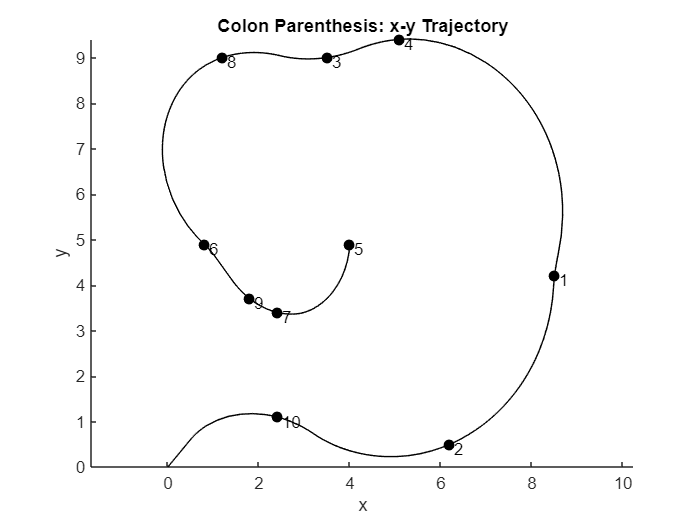

% Loads the final solution
clear;
load ColonParenthesis_solution.mat
final_sol = final_solution.sol;
city_sequence = final_solution.city_sequence;
final_r = final_solution.r;
final_time = final_cost.time;
final_J = final_cost.J;

% Useful variables
mesh_size = size(final_sol.x,2);
number_of_paths = size(city_sequence,2);

% Preallocates the time and state variables
times = [0;final_sol.parameters]; % times at each point: origin to last city (1x11)
for i = (1+1):(number_of_paths+1)
    times(i) = times(i) + times(i-1);
end
t = zeros(1,mesh_size*number_of_paths);
x = zeros(1,mesh_size*number_of_paths);
y = zeros(1,mesh_size*number_of_paths);
theta = zeros(1,mesh_size*number_of_paths);
v = zeros(1,mesh_size*number_of_paths);
lambda_x = zeros(1,mesh_size*number_of_paths);
lambda_y = zeros(1,mesh_size*number_of_paths);
lambda_theta = zeros(1,mesh_size*number_of_paths);
lambda_v = zeros(1,mesh_size*number_of_paths);

% This loop creates a single row vector for each state at every value of time
for i = 1:number_of_paths
    t(mesh_size*(i-1)+1 : mesh_size*i) = times(i) + final_sol.x*final_sol.parameters(i);
    x(mesh_size*(i-1)+1 : mesh_size*i) = final_sol.y(8*i-7,:);
    y(mesh_size*(i-1)+1 : mesh_size*i) = final_sol.y(8*i-6,:);
    theta(mesh_size*(i-1)+1 : mesh_size*i) = final_sol.y(8*i-5,:);
    v(mesh_size*(i-1)+1 : mesh_size*i) = final_sol.y(8*i-4,:);
    lambda_x(mesh_size*(i-1)+1 : mesh_size*i) = final_sol.y(8*i-3,:);
    lambda_y(mesh_size*(i-1)+1 : mesh_size*i) = final_sol.y(8*i-2,:);
    lambda_theta(mesh_size*(i-1)+1 : mesh_size*i) = final_sol.y(8*i-1,:);
    lambda_v(mesh_size*(i-1)+1 : mesh_size*i) = final_sol.y(8*i,:);
end

% Plots x, y, and cities
figure
hold on
plot(x, y, '-k', city_sequence(1,1:10),city_sequence(2,1:10),'xk')
plot(city_sequence(1,:), city_sequence(2,:), 'ko', 'MarkerFaceColor','k');
cities = [8.5  4.2;
          6.2  0.5;
          3.5  9.0;
          5.1  9.4;
          4.0  4.9;
          0.8  4.9;
          2.4  3.4;
          1.2  9.0;
          1.8  3.7;
          2.4  1.1]';
for i = 1:number_of_paths
    text(cities(1,i)+0.1, cities(2,i)-0.1, sprintf('%d', i));
end
axis equal
title('Colon Parenthesis: x-y Trajectory')
xlabel('x')
ylabel('y')

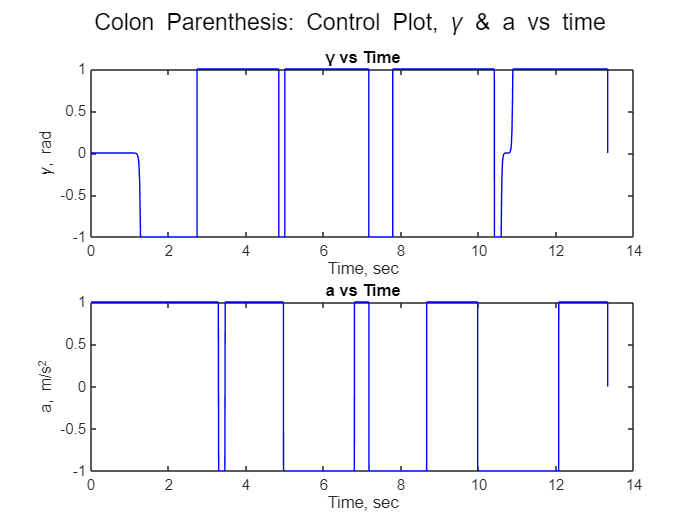


% Plots a, γ vs time
figure
hold on

% calculates a and γ
gamma = -(final_r/2)*lambda_theta;
a = -(final_r/2)*lambda_v;
for n = 1:length(gamma)
    if abs(gamma(n)) > 1
        gamma(n) = sign(gamma(n)); 
    end
    if abs(a(n)) > 1
        a(n) = sign(a(n));
    end
end

% Plots γ vs time
subplot(2,1,1)
plot(t, gamma, '-b')
xlabel('Time, sec')
ylabel('\gamma, rad')
title('γ vs Time')
% Plots a vs time
subplot(2,1,2)
plot(t, a, '-b')
xlabel('Time, sec')
ylabel('a, m/s^2')
title('a vs Time')
sgtitle('Colon Parenthesis: Control Plot, \gamma & a vs time')

## Functions

These are all the same functions as the functions with the same names in Path.mlx. They are used to perform the bvp4c command. Their individual descriptions can be found in Path.mlx.

function ds = ODEs (~,s, r)
% s(1) = x, s(2) = y, s(3) = theta, s(4) = v, s(5) = lambda_x, s(6) =
% lambda(y), s(7) = lambda_theta, s(8) = lambda_v

gamma = -(r/2)*s(7);
if abs(gamma) > 1
    gamma = sign(gamma); 
end
a = -(r/2)*s(8); 
if abs(a) > 1
    a = sign(a); 
end

ds(1,1) = s(4)*cos(s(3)); 
ds(2,1) = s(4)*sin(s(3)); 
ds(3,1) = gamma; 
ds(4,1) = a; 
ds(5,1) = 0; 
ds(6,1) = 0; 
ds(7,1) = s(5)*s(4)*sin(s(3)) - s(6)*s(4)*cos(s(3)); 
ds(8,1) = -s(5)*cos(s(3)) - s(6)*sin(s(3)); 

end



function ds = ODEmain(t,s,times, r)   % three default inputs into ODEmain
% s(1:8) arc 1
% s(9:16) arc 2
% times = [t1, t2]
% ds(1:8, 1) = ODEs(t,s(1:8),r)*times(1); 
% ds(9:16, 1) = ODEs(t,s(9:16),r)*times(2);   % put this in a loop? to do not just two cities but potentially ten cities depending on what you want to pass in

% s(8*i-7:8*i) arc i

ds = zeros(size(s)); % Preallocation for ds

for i = 1:length(times)
    ds(8*i-7:8*i, 1) = ODEs(t,s(8*i-7:8*i),r)*times(i);
end    

end



function H = Hamiltonian(s,r)

gamma = -(r/2)*s(7); 
if abs(gamma)>1 
    gamma = sign(gamma); 
end
a = -(r/2)*s(8); 
if abs(a) >1
    a = sign(a); 
end
H = 1 +(1/r)*(gamma^2 +a^2)+ s(5)*s(4)*cos(s(3))+s(6)*s(4)*sin(s(3))+s(7)*gamma+s(8)*a; 

end



function con = bcfunc(so,sf,times,r,city_sequence)

% s(1) = x, s(2) = y, s(3) = theta, s(4) = v, s(5) = lambda_x
% s(6) = lambda_y, s(7) = lambda_theta, s(8) = lambda_v

% Initial Constraints
con(1) = so(1); % x(0) = 0
con(2) = so(2); % y(0) = 0
con(3) = so(7); % lambda_theta(0) = 0
con(4) = so(4); % v(0) = 0

for i = 1:(length(times) - 1)
    con(9*i-4) = (sf(8*(i-1)+1) - city_sequence(1,i));                        % Intermediate Constraints
    con(9*i-3) = (sf(8*(i-1)+2) - city_sequence(2,i));                        % Intermediate Constraints
    con((9*i-2):(9*i+1)) = sf((8*(i-1)+1):(8*(i-1)+4)) - so((8*i+1):(8*i+4)); % Continuity (x,y,theta,v)
    con((9*i+2):(9*i+3)) = sf((8*(i-1)+7):(8*(i-1)+8)) - so((8*i+7):(8*i+8)); % Continuity (x,y,theta,v)
    con(9*i+4) = Hamiltonian(sf((8*(i-1)+1):(8*(i-1)+8)),r);                  % Transversality Conditions
end

% Terminal Constraints
con(9*i+5) = sf(8*i+1) - city_sequence(1,i+1); % Final city x
con(9*i+6) = sf(8*i+2) - city_sequence(2,i+1); % Final city y
con(9*i+7) = sf(end-1);                        % lambda_theta(tf)
con(9*i+8) = sf(end);                          % lambda_v(tf)
con(9*i+9) = Hamiltonian(sf((8*i+1):(8*i+8)),r);

end